**Calculate the Change in Centre of Gravity of Geyser from being completely filled to completely empty**

% Geyer of Outer Diameter 44 cm and Inner Diameter 40 cm and height of 80 cm
% The bottom plate of Geyser is 44cm in diameter with thickness of 6 cm.
% Water is assumed to be a solid cylinder of diameter 40 cm and height 80 cm.

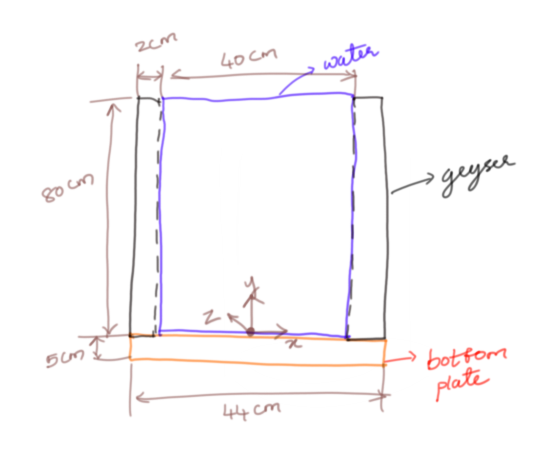

%Variables in cm
%Geyser Cylinder
g_din = 40; % Inner Diameter of Geyser
g_dout = 41; % Outer Diameter of Geyser
g_th = 2; % Wall thickness of Geyser
g_h = 80; % Height of Geyser
g_rho = 8 ; % Density of steel in g/cu.cm

%Bottom Plate
b_dia = 44; % Diameter of Bottom plate
b_h = 0; % Height of Bottom plate
b_rho = g_rho ; % Density of steel in g/cu.cm


%Water
w_dia = g_din; % Diameter of Water = Inner Diameter of Geyser
w_h = g_h; % Initial height of water = height of geyser
w_rho = 1; % Density of water in g/cu.cm

%Calculating Mass = Density x Volume
g_m_out = (g_rho * pi * (g_dout * g_dout * g_h))/4; % Mass of geyser outer diameter
g_m_in =  (g_rho * pi * (g_din * g_din * g_h))/4; % Mass of geyser Inner diameter
b_m = (b_rho * pi * (b_dia * b_dia * b_h))/4; % Mass of Bottom Plate
w_m = (w_rho * pi *(w_dia * w_dia * w_h))/4; % Mass of Water

% x, y, z coordinates with reference to the datum origin as shown in diagram

[g_out_x, g_out_y, g_out_z] = deal(0, g_h/2 ,0);
[g_in_x, g_in_y, g_in_z] = deal(0, g_h/2 ,0);
[b_x, b_y, b_z] = deal(0, -b_h/2 ,0);
[w_x, w_y, w_z] = deal(0, w_h/2 ,0);

%Calculate Centre of Gravity CG_x, CG_y, CG_z

[CG_x, CG_y, CG_z] = CalcCentreOfGravity(g_din, g_dout, g_h, g_rho, b_dia, b_h, b_rho, ...
                                            w_dia, w_h, w_rho);
disp(CG_x);

     0



disp(CG_y);

   40.0000



disp(CG_z);

     0



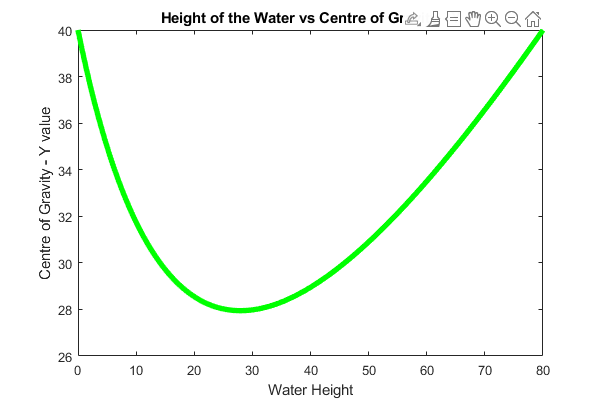



index = 1;
inc = -0.1;
CG = zeros(((w_h+0)/abs(inc))+1,4);


for i=w_h:inc:0
    [CG_x, CG_y, CG_z] = CalcCentreOfGravity(g_din, g_dout, g_h, g_rho, b_dia, b_h, b_rho, ...
                                            w_dia, i, w_rho);
    CG(index,1) = i;
    CG(index,2) = CG_x;
    CG(index,3) = CG_y;
    CG(index,4) = CG_z;
    index = index +1;
end

CGY = figure;
CGY.Position = [800 600 600 400];
plot(CG(:,1),CG(:,3),"LineStyle","-","Color",'g','LineWidth',4);
title("Height of the Water vs Centre of Gravity - Y");
xlabel("Water Height");
ylabel("Centre of Gravity - Y value");
set(CGY, 'Visible', 'on');

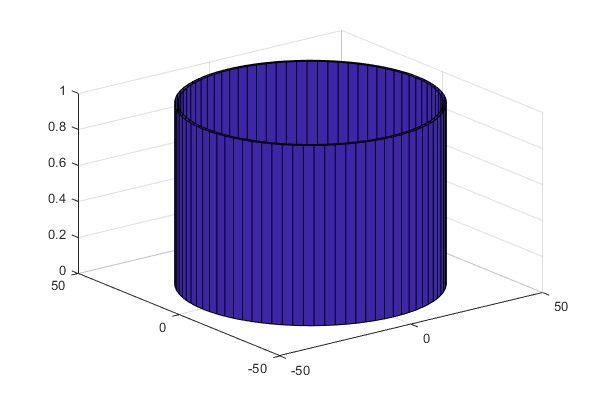


Mod = figure('Position',[200 600 600 400]);
cylinder(g_dout, g_h);
hold on;
cylinder(w_dia, w_h);
hold off;
set(Mod, 'Visible', 'on');

**Function to Calculate the Centre of Gravity**

    function [CG_x, CG_y, CG_z] = CalcCentreOfGravity( ...
                                    g_din, g_dout, g_h, g_rho, b_dia, b_h, b_rho, ...
                                    w_dia, w_h, w_rho)

    %Calculating Mass = Density x Volume
    g_m_out = (g_rho * pi * (g_dout * g_dout * g_h))/4; % Mass of geyser outer diameter
    g_m_in =  (g_rho * pi * (g_din * g_din * g_h))/4; % Mass of geyser Inner diameter
    b_m = (b_rho * pi * (b_dia * b_dia * b_h))/4; % Mass of Bottom Plate
    w_m = (w_rho * pi *(w_dia * w_dia * w_h))/4; % Mass of Water

    % x, y, z coordinates with reference to the datum origin as shown in diagram
    [g_out_x, g_out_y, g_out_z] = deal(0, g_h/2 ,0);
    [g_in_x, g_in_y, g_in_z] = deal(0, g_h/2 ,0);
    [b_x, b_y, b_z] = deal(0, -b_h/2 ,0);
    [w_x, w_y, w_z] = deal(0, w_h/2 ,0);

    CG_x = (g_m_out * g_out_x - g_m_in * g_in_x + b_m * b_x + w_m * w_x)/(g_m_out - g_m_in + b_m + w_m);
    CG_y = (g_m_out * g_out_y - g_m_in * g_in_y + b_m * b_y + w_m * w_y)/(g_m_out - g_m_in + b_m + w_m);
    CG_z = (g_m_out * g_out_z - g_m_in * g_in_z + b_m * b_z + w_m * w_z)/(g_m_out - g_m_in + b_m + w_m);
end